# Side-By-Side Images

This example shows how to arrange images side by side on a page.

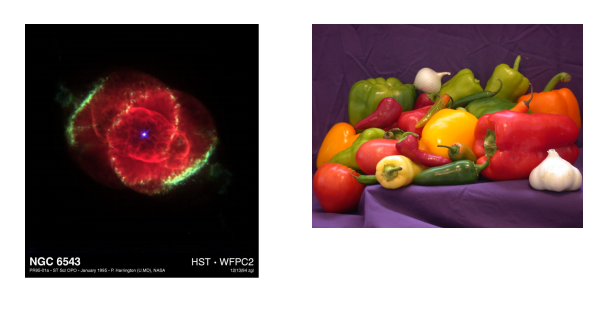

Import the DOM and Report API packages so you do not have to use long, fully-qualified class names, and create the report.

import mlreportgen.dom.*
import mlreportgen.report.*

% To create a Word report, change the output type from "pdf" to "docx". 
% To create an HTML report, change "pdf" to "html" or "html-file" for 
% a multifile or single-file report, respectively.
rpt = Report('myreport', 'pdf');

Create two image objects wrapped around corresponding image files. Scale the images to fit the invisible table cells created below.

imgStyle = {ScaleToFit(true)};
img1 = Image(which('ngc6543a.jpg'));
img1.Style = imgStyle;
img2 = Image(which('peppers.png'));
img2.Style = imgStyle;

Insert images in the row of  a 1x3, invisible layout table (lot).

lot = Table({img1, ' ', img2});

The images will be sized to fit the table entries only if their height and width is specified.

lot.entry(1,1).Style = {Width('3.2in'), Height('3in')};
lot.entry(1,2).Style = {Width('.2in'), Height('3in')};
lot.entry(1,3).Style = {Width('3.2in'), Height('3in')};

 Make the table span the width of the page between the margins. Tell the table layout manager to not resize the table columns to fit the images.

lot.Style = {ResizeToFitContents(false), Width('100%')};

Generate and display the report.

add(rpt, lot);
close(rpt);
rptview(rpt);


*Copyright 2018 The MathWorks, Inc.*